# Introduction

Implementation of Spiliopoulos' inter-bank reserves model with networks. We increase the number of Banks, $N$, from 10 to 100 in order for the network effects to be more prevalent.


$$\mathrm{d}X_t^i = \frac{\theta_{i}}{N}\sum_{j=1}^{N} a_{i,j} \left(X_{t}^{j} - X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}W^{i}_{t}$$


# Baseline - Homogeneous Banks

Homogeneous banks ($N = 100, a = 1, \sigma = 1$), all-to-all coupling.

baseline = model(10, ones(10, 1), ones(10, 1));
baseline = baseline.sde_euler;
baseline = baseline.monte_carlo(5000);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).


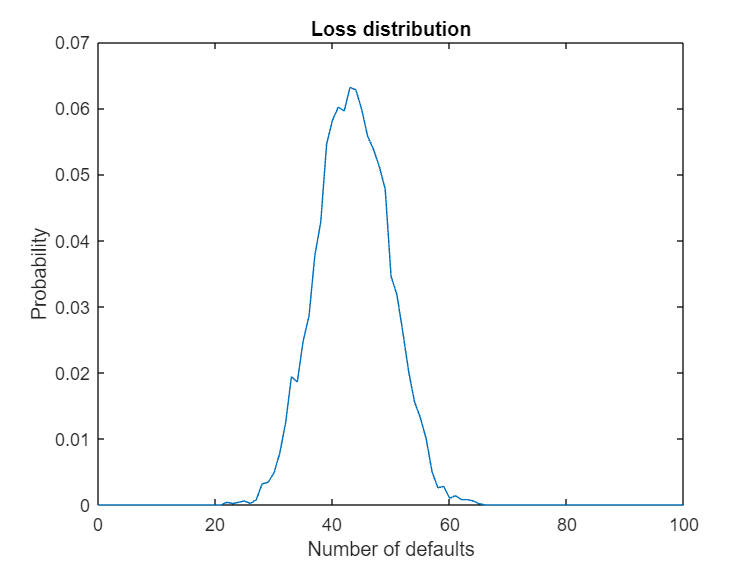

baseline.plot_loss;

fprintf("Probability of systemic failure: %.2f", baseline.probfail);

Probability of systemic failure: 0.00

## Erdos Renyi

erdosrenyi = baseline.erdosrenyi(0.5);
erdosrenyi = erdosrenyi.network;
erdosrenyi = erdosrenyi.sde_euler;
erdosrenyi = erdosrenyi.monte_carlo(5000);

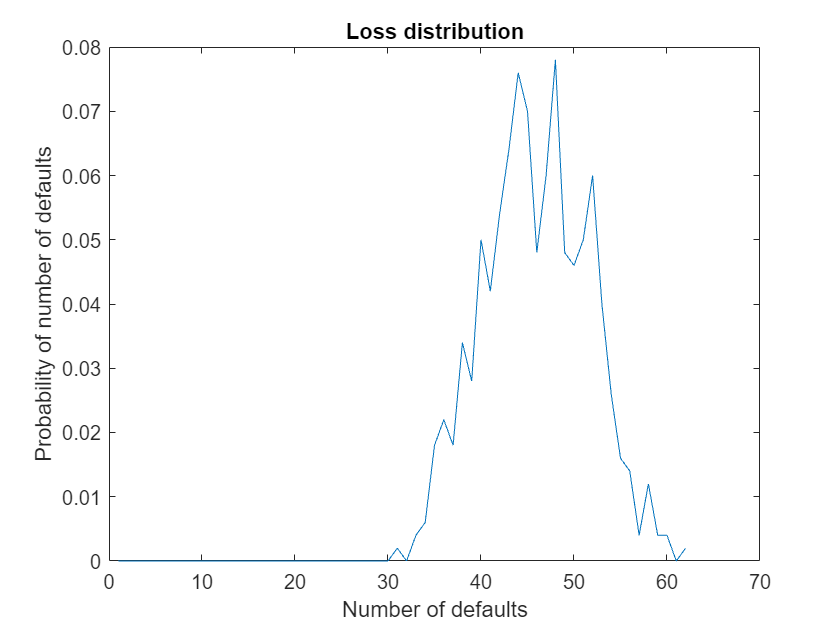

erdosrenyi.plot_loss;

fprintf("Probability of systemic failure: %.2f", erdosrenyi.probfail);

## Homophily

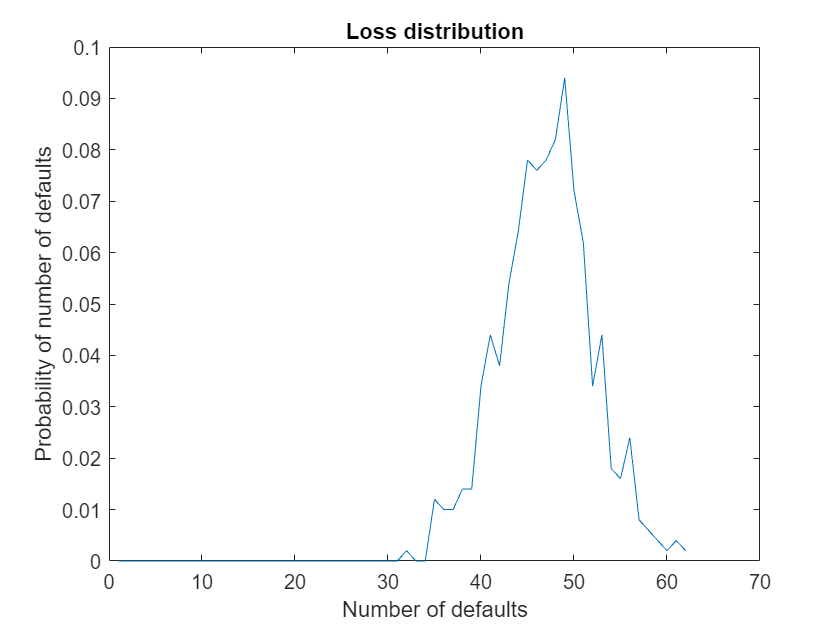

homophily = baseline.homophily(0.5);
homophily = homophily.sde_euler;
homophily.plot_loss;

## Heterophily

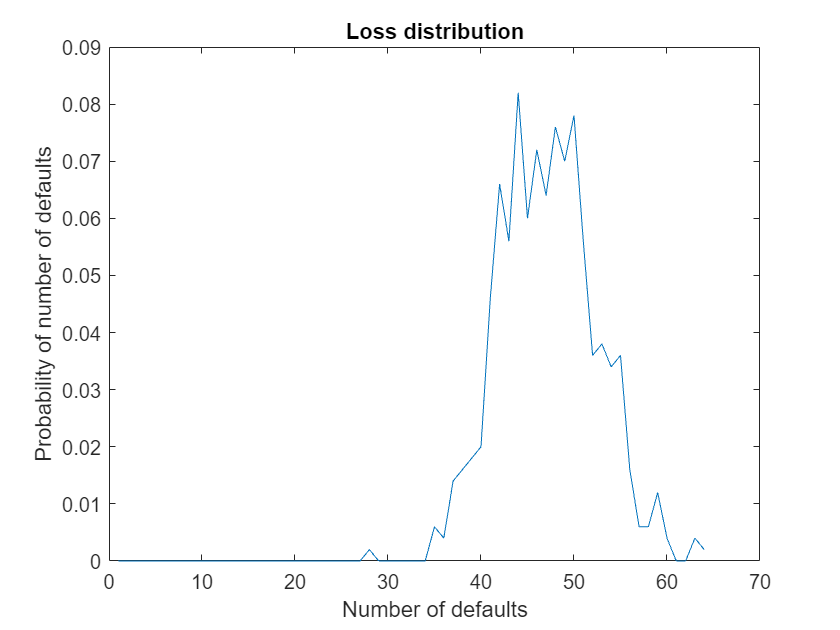

heterophily = baseline.heterophily(0.5);
heterophily = heterophily.sde_euler;
heterophily.plot_trajectory;
heterophily.plot_loss;

# Group A


$$\mathrm{d}X_t^i = \frac{\theta_{i}}{N}\sum_{j=1}^{N} a_{i,j} \left(X_{t}^{j} - X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}W^{i}_{t}$$


$(\theta, \sigma) = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$with ratios $\{0.2, 0.5, 0.3\}$.

Agents with small coefficients $a_i$ have large coefficients $\sigma_i$,while agents with large coefficients $a_i$ have small coefficients $\sigma_i$.

## Baseline

model_A = model(10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(2, 2, 1); repelem(1, 5, 1); repelem(0.5, 3, 1)] ...
    );
model_A = model_A.monte_carlo(5000);

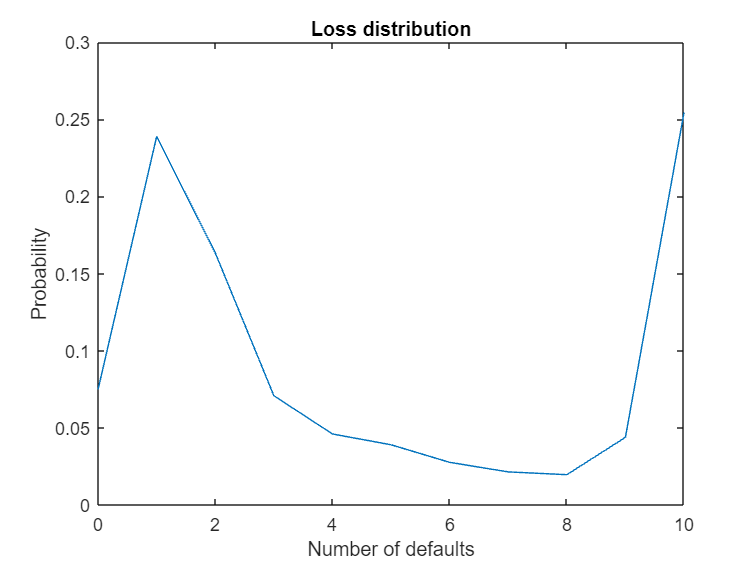

model_A.plot_loss;

fprintf("Probability of systemic failure: %.2f", model_A.probfail);

Probability of systemic failure: 0.32

# Group A with networks

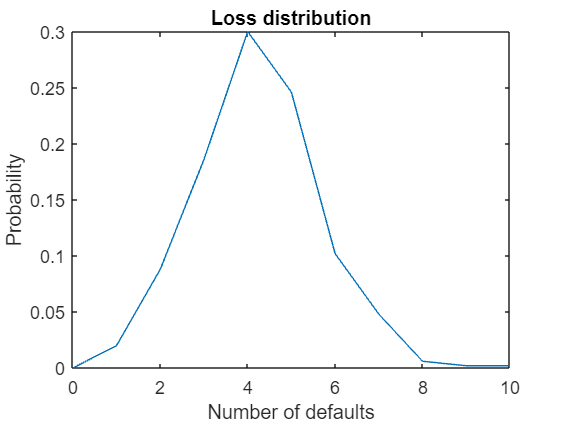

no_coupling_a = model_A.erdosrenyi(0);
no_coupling_a = no_coupling_a.network;
no_coupling_a = no_coupling_a.monte_carlo(500);
no_coupling_a.plot_loss;

## Erdos-Renyi

We assume the adjacency matrix takes values


$$$$
a_{i,j}=
\begin{cases}
1 & \text{with probability } p \\
0 & \text{with probability } 1-p
\end{cases}
\quad \text{for } \quad i, j = 1, \dots, N
$$$$


erdosrenyi_a = model_A.erdosrenyi(0.25);
erdosrenyi_a = erdosrenyi_a.network;
erdosrenyi_a = erdosrenyi_a.monte_carlo(5000);

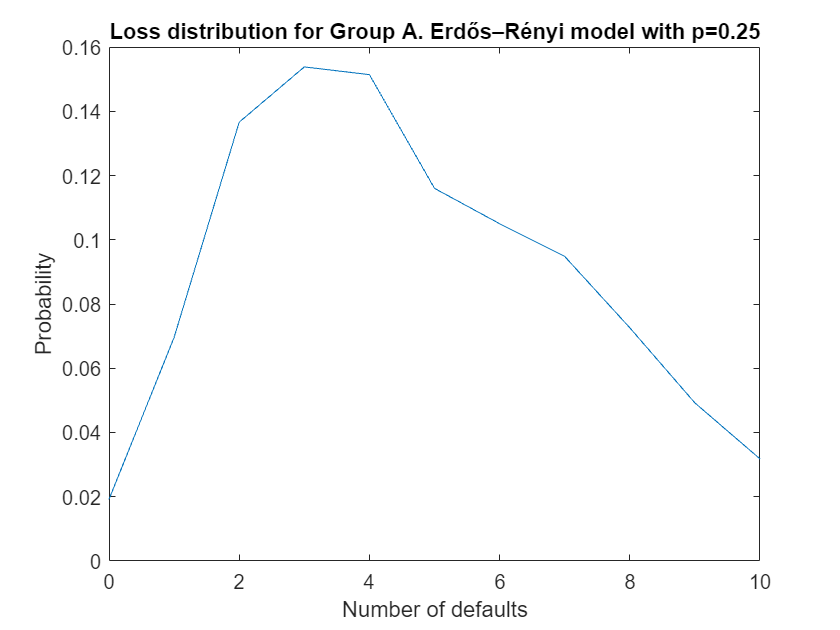

erdosrenyi_a.plot_loss;
title('Loss distribution for Group A. Erdős–Rényi model with p=0.25');

fprintf("Probability of systemic failure: %.2f", erdosrenyi_a.probfail);

Probability of systemic failure: 0.20

## Star

In a star-network, some banks are fully connected while others are sparsely connected

### Small banks fully-connected

star_a_small = model_A.star(1, 2);
star_a_small = star_a_small.network;
star_a_small = star_a_small.monte_carlo(5000);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 6).


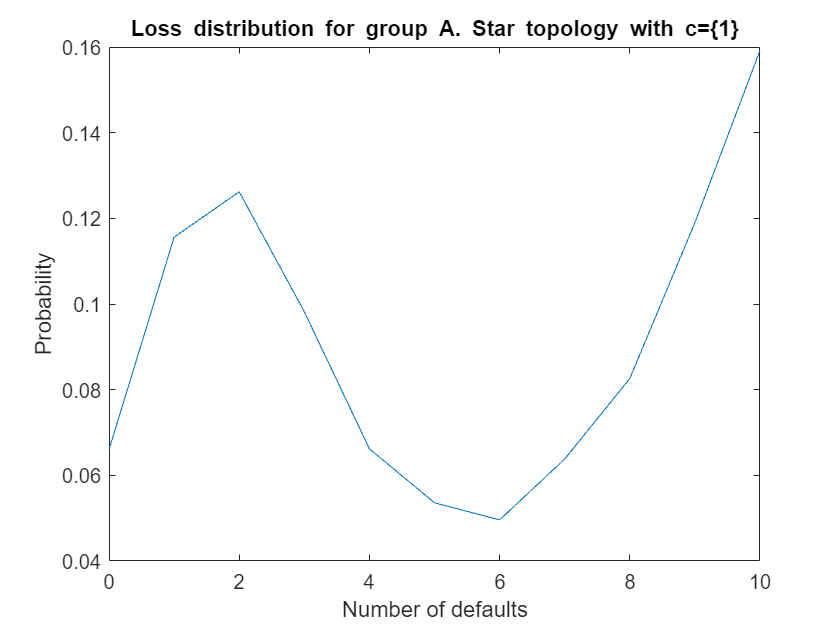

star_a_small.plot_loss;
title('Loss distribution for group A. Star topology with c=\{1,2\}');

fprintf("Probability of systemic failure: %.2f", star_a_small.probfail);

Probability of systemic failure: 0.34

### Intermediate banks fully-connected

star_a_med = model_A.star(3, 7);
star_a_med = star_a_med.network;
star_a_med = star_a_med.monte_carlo(5000);

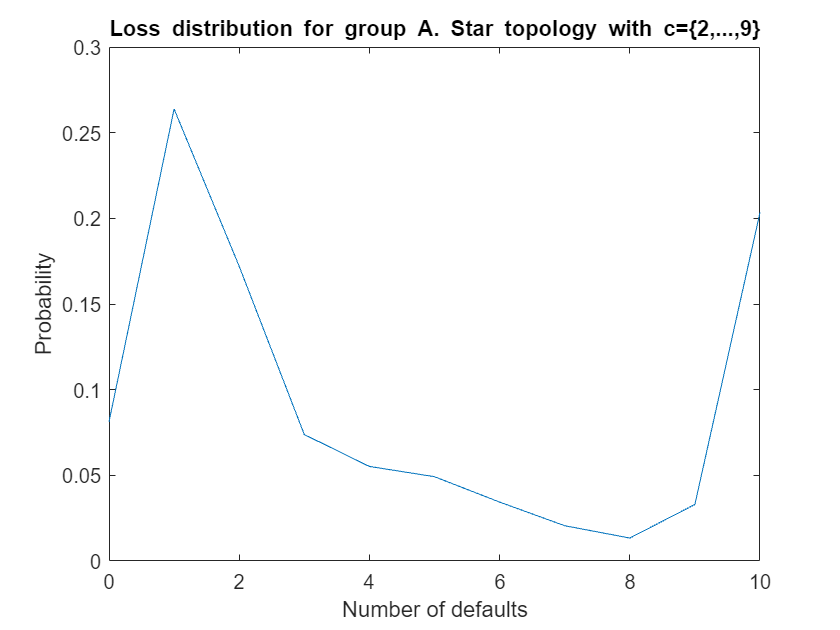

star_a_med.plot_loss;
title('Loss distribution for group A. Star topology with c=\{3,...,7\}');

fprintf("Probability of systemic failure: %.2f", star_a_med.probfail);

Probability of systemic failure: 0.26

### Large banks fully-connected

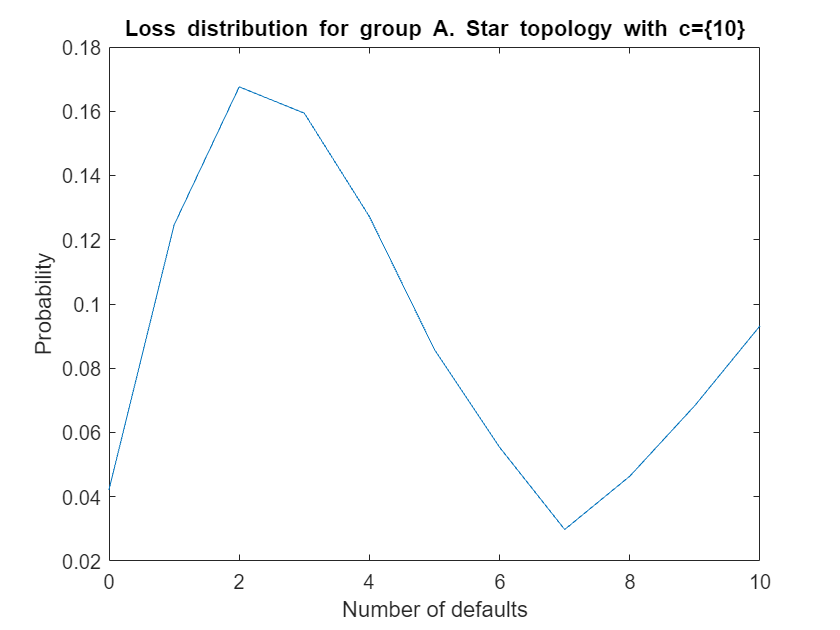

star_a_large = model_A.star(8, 10);
star_a_large = star_a_large.network;
star_a_large = star_a_large.monte_carlo(5000);
star_a_large.plot_loss;
title('Loss distribution for group A. Star topology with c=\{8,...,10\}');

fprintf("Probability of systemic failure: %.2f", star_a_large.probfail);

Probability of systemic failure: 0.23

## Homophily

We assume that the adjacency matrix is of the form:


$$$$
a_{i,j}=
\begin{cases}
1, & \text{if } \quad |x_{i} - x_{j}| \leq \tau \\
0, & \text{if } \quad |x_{i} - x_{j}| > \tau
\end{cases}
\quad \text{for } \quad i, j = 1, \dots, N
$$$$


where $\tau$ denotes the radius of interactions - the maximum distance allowed between $x_{i}$ and $x_{j}$ for them to continue interacting with each other.

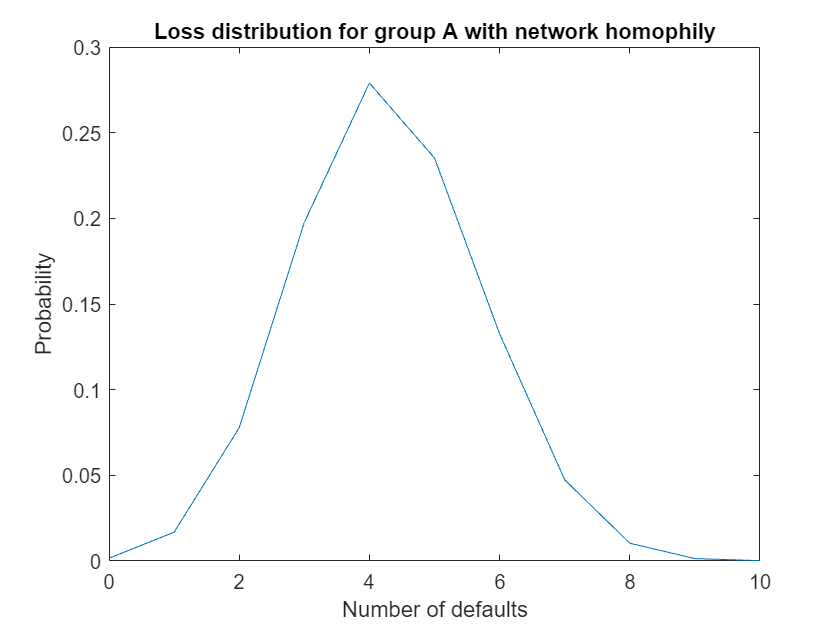

homophily_a = model_A.homophily(0.5);
homophily_a = homophily_a.monte_carlo(5000);
homophily_a.plot_loss;
title('Loss distribution for group A with network homophily');

fprintf("Probability of systemic failure: %.2f", homophily_a.probfail);

Probability of systemic failure: 0.06

## Heterophily

We assume that the adjacency matrix is of the form:

$$$
a_{i,j}=
\begin{cases}
1, & \text{if } \quad |x_{i} - x_{j}| > \tau \\
0, & \text{if } \quad |x_{i} - x_{j}| \leq \tau
\end{cases}
\quad \text{for } \quad i, j = 1, \dots, N, i \neq j
$$$, with $\{a_{i,i}\}_{i=1}^{N} = 1$.

where $\tau$ denotes the radius of interactions - the minimum distance allowed between $x_{i}$ and $x_{j}$ for them to continue interacting with each other. 


$$\tau = 0.2$$


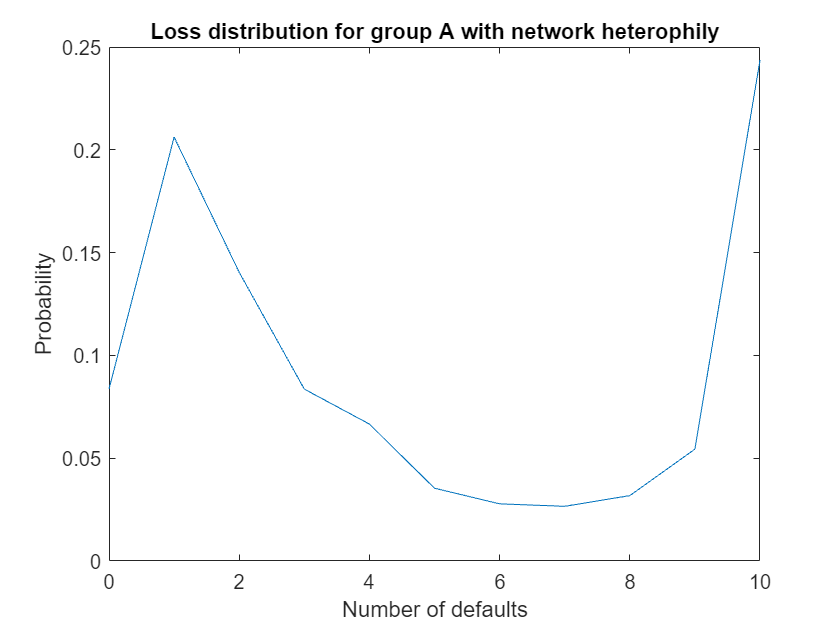

heterophily_a = model_A.heterophily(0.5);
heterophily_a = heterophily_a.monte_carlo(5000);
heterophily_a.plot_loss;
title('Loss distribution for group A with network heterophily');

fprintf("Probability of systemic failure: %.2f", heterophily_a.probfail);

Probability of systemic failure: 0.32

# Group B


$$\mathrm{d}X_t^i = \frac{\theta_{i}}{N}\sum_{j=1}^{N} a_{i,j} \left(X_{t}^{j} - X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}W^{i}_{t}$$


$(\theta, \sigma) = \left\{(1, 0.5), (10, 1), (100, 2)\right\}$ with ratios $\{0.2, 0.5, 0.3\}$.

Agents with small coefficients $a_i$ have also small coefficients $\sigma_i$ and agents with large coefficients $a_i$ also have large coefficients $\sigma_i$.

model_B = model(10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(0.5, 2, 1); repelem(1, 5, 1); repelem(2, 3, 1)] ...
    );
model_B = model_B.monte_carlo(5000);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 6).


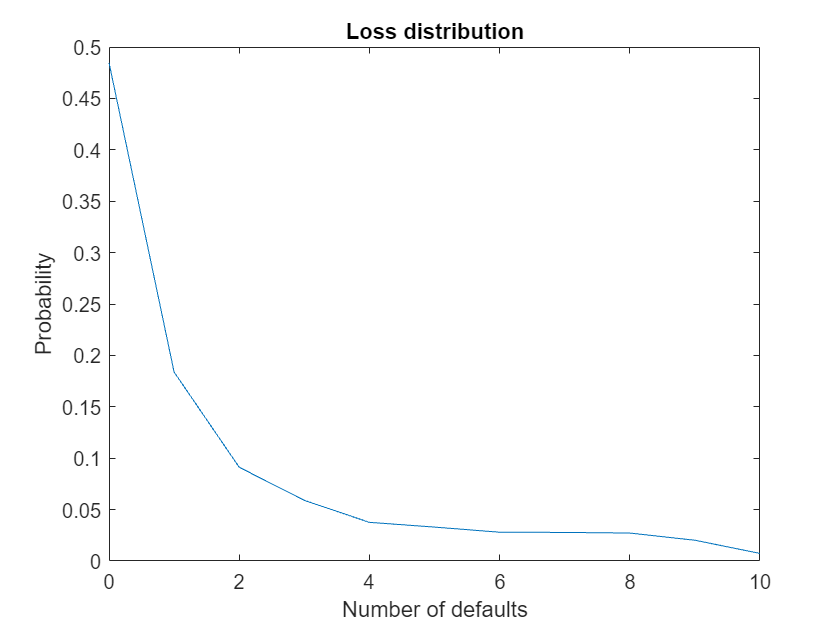

model_B.plot_loss;

fprintf("Probability of systemic failure: %.2f", model_B.probfail);

Probability of systemic failure: 0.01

erdosrenyi_b = model_B.erdosrenyi(0.25);
erdosrenyi_b = erdosrenyi_b.network;
erdosrenyi_b = erdosrenyi_b.monte_carlo(5000);

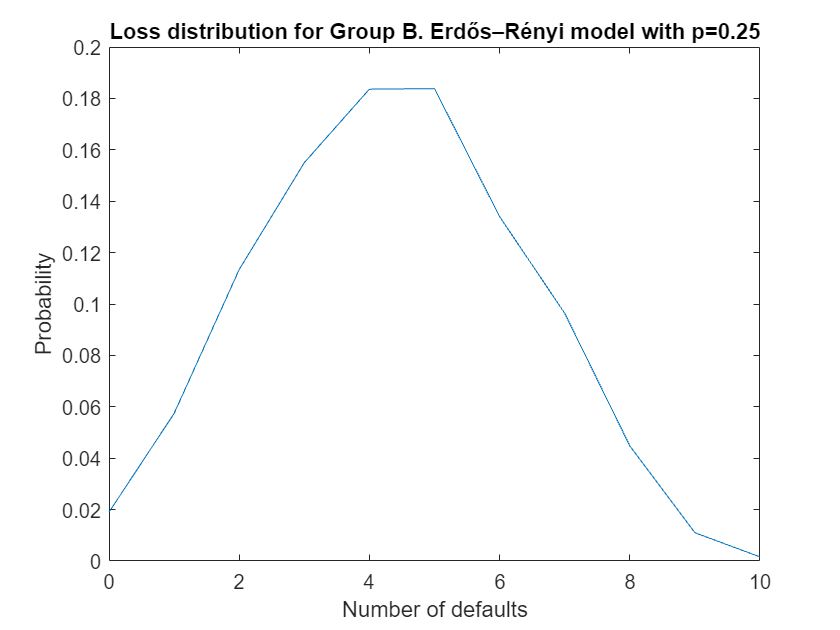

erdosrenyi_b.plot_loss;
title('Loss distribution for Group B. Erdős–Rényi model with p=0.25');

fprintf("Probability of systemic failure: %.2f", erdosrenyi_b.probfail);

Probability of systemic failure: 0.02

## Star

In a star-network, some banks are fully connected while others are sparsely connected

### Small banks fully-connected

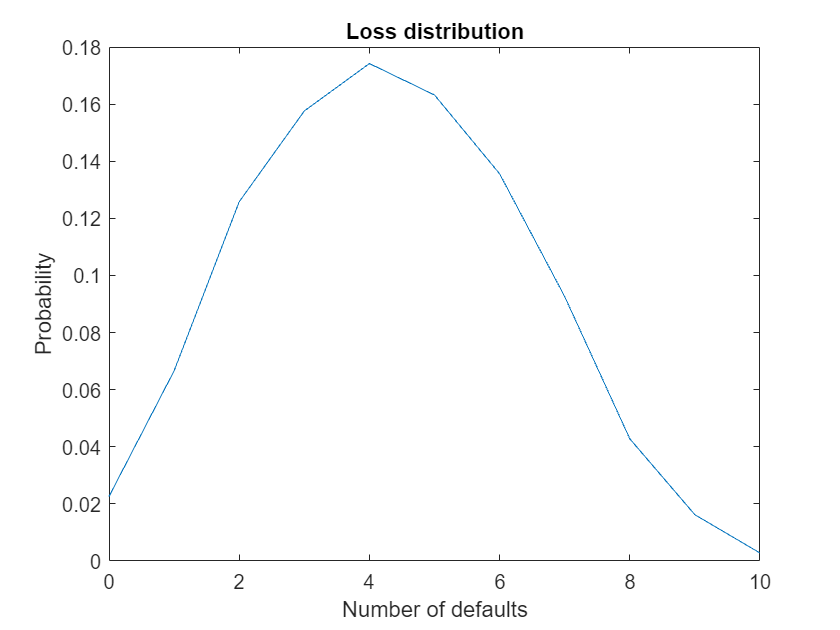

star_b_small = model_B.star(1, 2);
star_b_small = star_b_small.network;
star_b_small = star_b_small.monte_carlo(5000);
star_b_small.plot_loss;

fprintf("Probability of systemic failure: %.2f", star_b_small.probfail);

Probability of systemic failure: 0.02

### Intermediate banks fully-connected

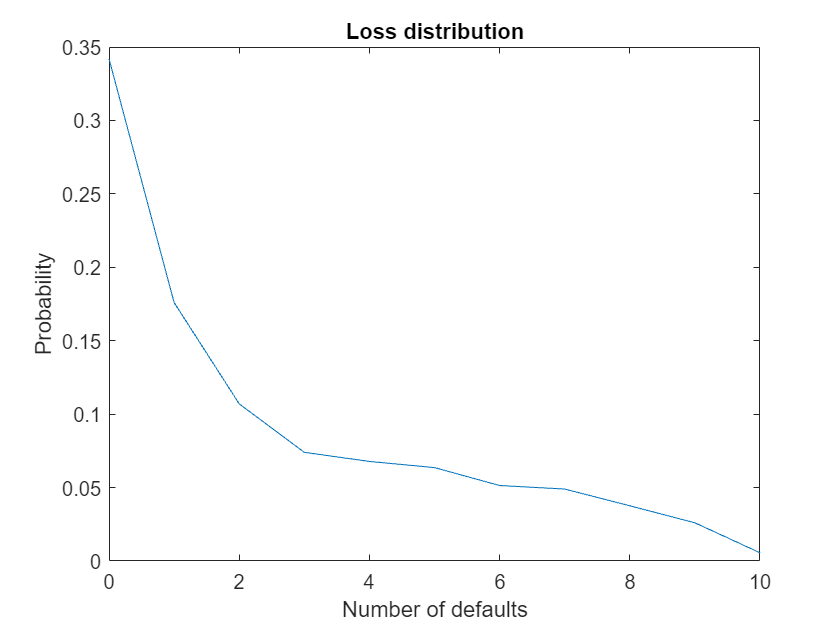

star_b_med = model_B.star(3, 7);
star_b_med = star_b_med.network;
star_b_med = star_b_med.monte_carlo(5000);
star_b_med.plot_loss;

fprintf("Probability of systemic failure: %.2f", star_b_med.probfail);

Probability of systemic failure: 0.02

### Large banks fully-connected

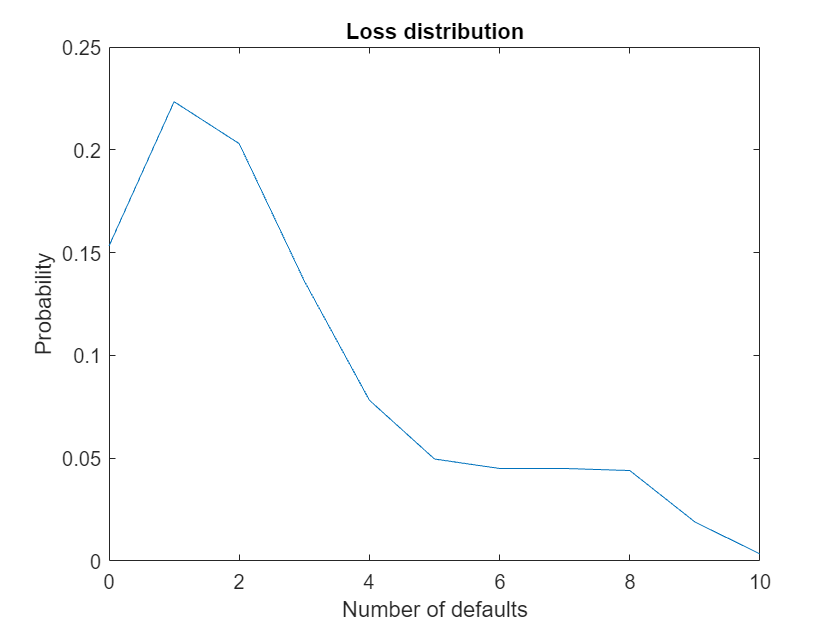

star_b_large = model_B.star(8, 10);
star_b_large = star_b_large.network;
star_b_large = star_b_large.monte_carlo(5000);
star_b_large.plot_loss;

fprintf("Probability of systemic failure: %.2f", star_b_large.probfail);

Probability of systemic failure: 0.02

## Homophily

homophily_b = model_B.homophily(0.5);
homophily_b = homophily_b.monte_carlo(5000);

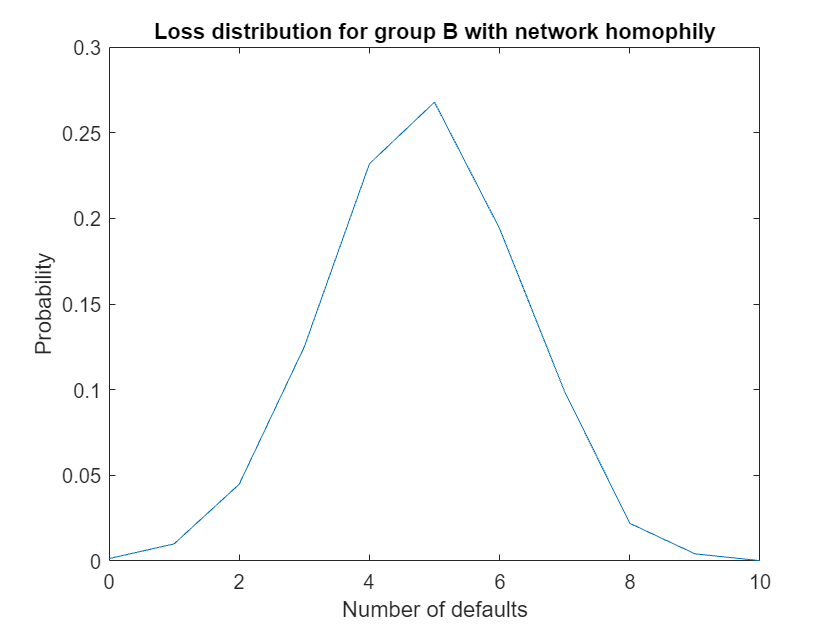

homophily_b.plot_loss;
title('Loss distribution for group B with network homophily');

fprintf("Probability of systemic failure: %.2f", homophily_b.probfail);

Probability of systemic failure: 0.09

## Heterophily

heterophily_b = model_B.heterophily(0.5);
heterophily_b = heterophily_b.monte_carlo(5000);

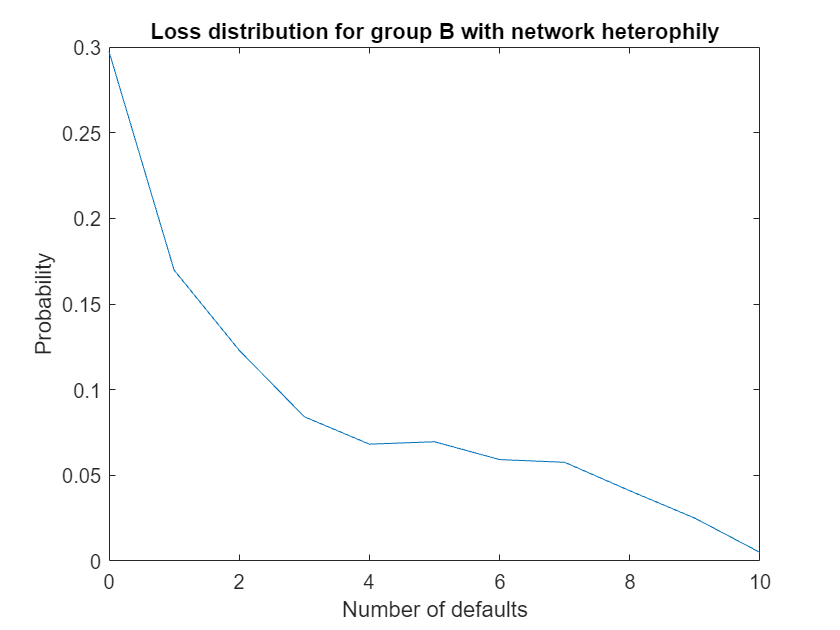

heterophily_b.plot_loss;
title('Loss distribution for group B with network heterophily');

fprintf("Probability of systemic failure: %.2f", heterophily_b.probfail);

Probability of systemic failure: 0.02

## Case 2: 1:8:1

Star network with one fully connected large bank

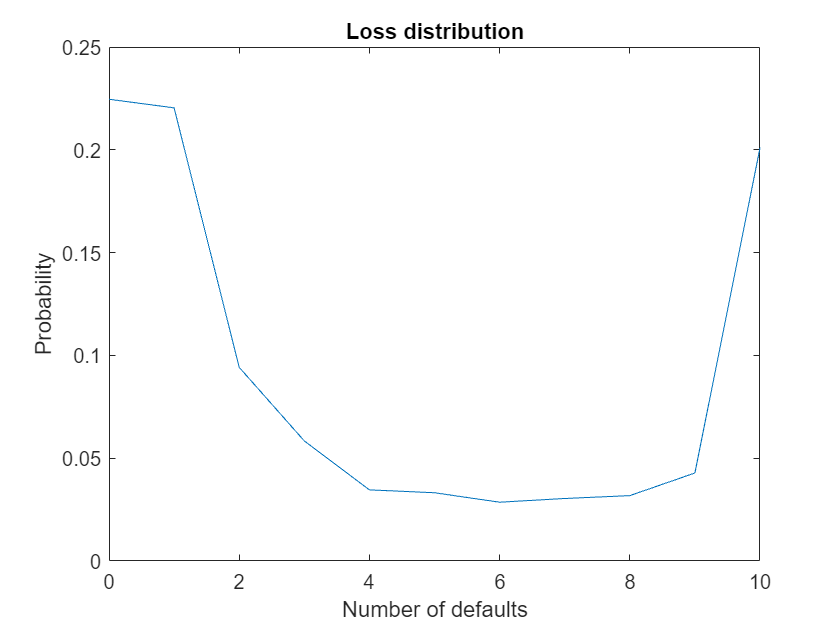

model_A2 = model(10, ...
    [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)], ...
    [repelem(2, 1, 1); repelem(1, 8, 1); repelem(1, 1, 1)] ...
    );
model_A2 = model_A2.monte_carlo(5000);
model_A2.plot_loss;

fprintf("Probability of systemic failure: %.2f", model_A2.probfail);

Probability of systemic failure: 0.24

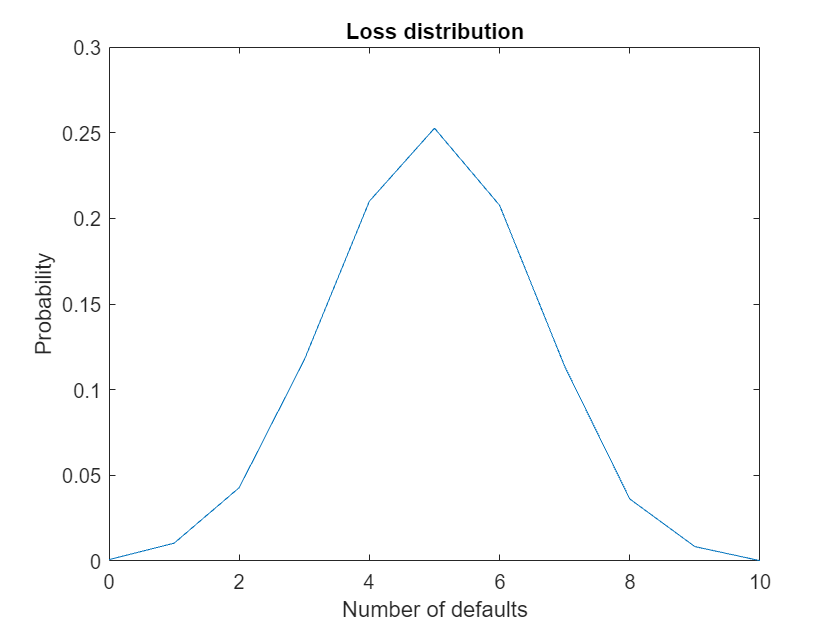

no_coupling_a2 = model_A2.erdosrenyi(0);
no_coupling_a2 = no_coupling_a2.network;
no_coupling_a2 = no_coupling_a2.monte_carlo(5000);
no_coupling_a2.plot_loss;

fprintf("Probability of systemic failure: %.2f", no_coupling_a2.probfail);

Probability of systemic failure: 0.05

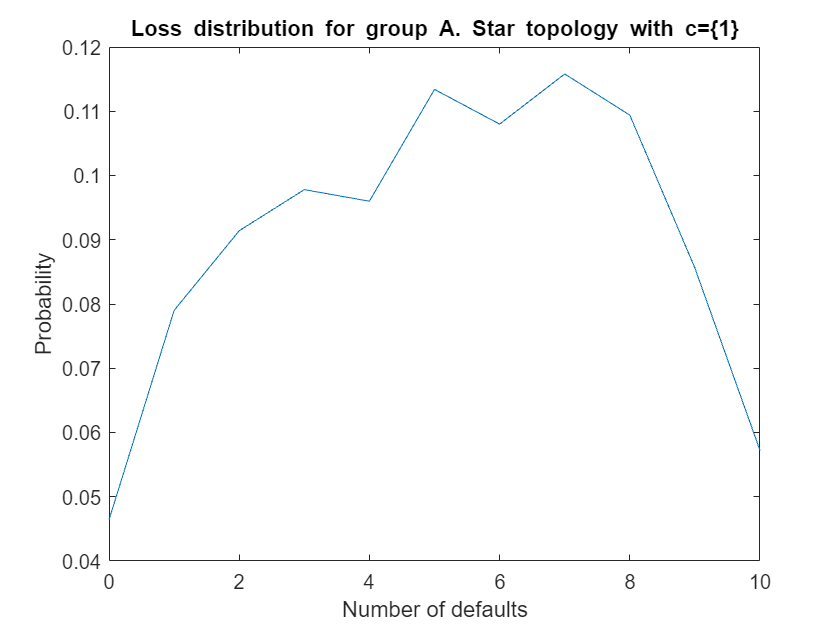

star_a2_small = model_A2.star(1, 1);
star_a2_small = star_a2_small.network;
star_a2_small = star_a2_small.monte_carlo(5000);
star_a2_small.plot_loss;
title('Loss distribution for group A. Star topology with c=\{1\}');

fprintf("Probability of systemic failure: %.2f", star_a2_small.probfail);

Probability of systemic failure: 0.26

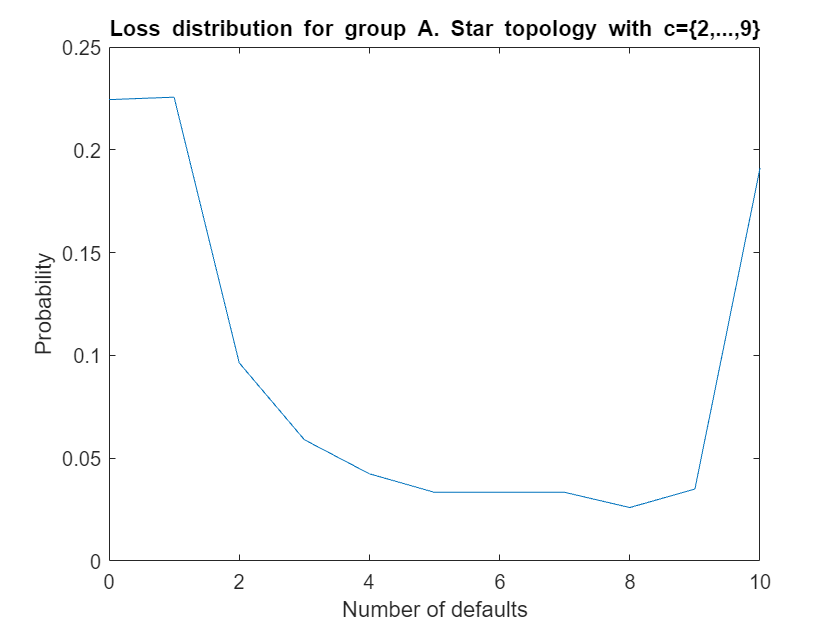

star_a2_med = model_A2.star(2, 9);
star_a2_med = star_a2_med.network;
star_a2_med = star_a2_med.monte_carlo(5000);
star_a2_med.plot_loss;
title('Loss distribution for group A. Star topology with c=\{2,...,9\}');

fprintf("Probability of systemic failure: %.2f", star_a2_med.probfail);

Probability of systemic failure: 0.22

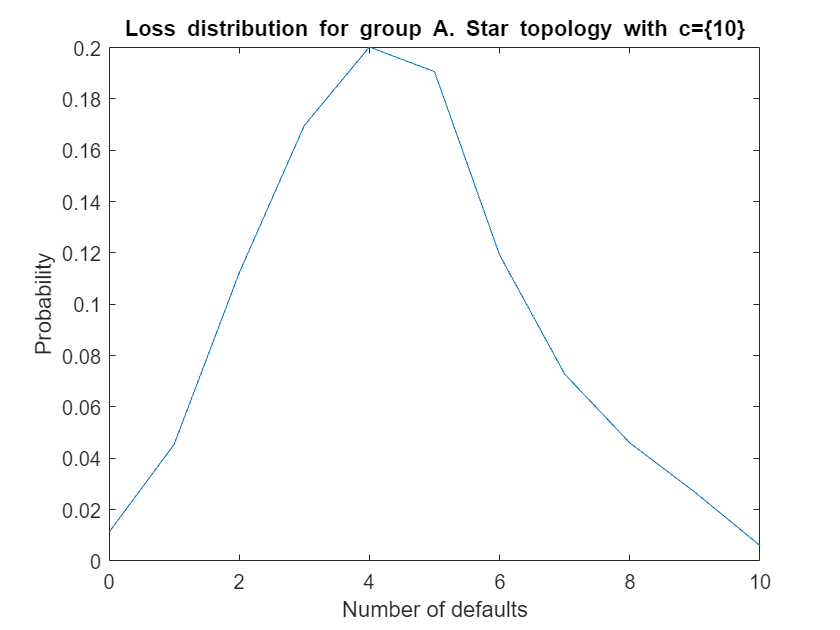

star_a2_large = model_A2.star(10, 10);
star_a2_large = star_a2_large.network;
star_a2_large = star_a2_large.monte_carlo(5000);
star_a2_large.plot_loss;
title('Loss distribution for group A. Star topology with c=\{10\}');

fprintf("Probability of systemic failure: %.2f", star_a2_large.probfail);

Probability of systemic failure: 0.09

model_B2 = model(10, ...
    [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)], ...
    [repelem(0.5, 1, 1); repelem(1, 8, 1); repelem(2, 1, 1)] ...
    );
model_B2 = model_B2.monte_carlo(5000);

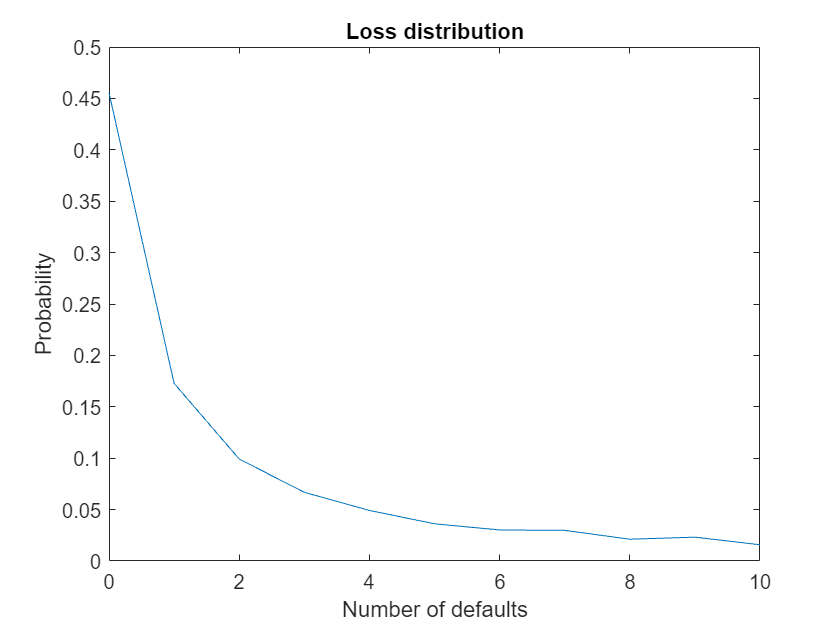

model_B2.plot_loss;

fprintf("Probability of systemic failure: %.2f", model_B2.probfail);

Probability of systemic failure: 0.02

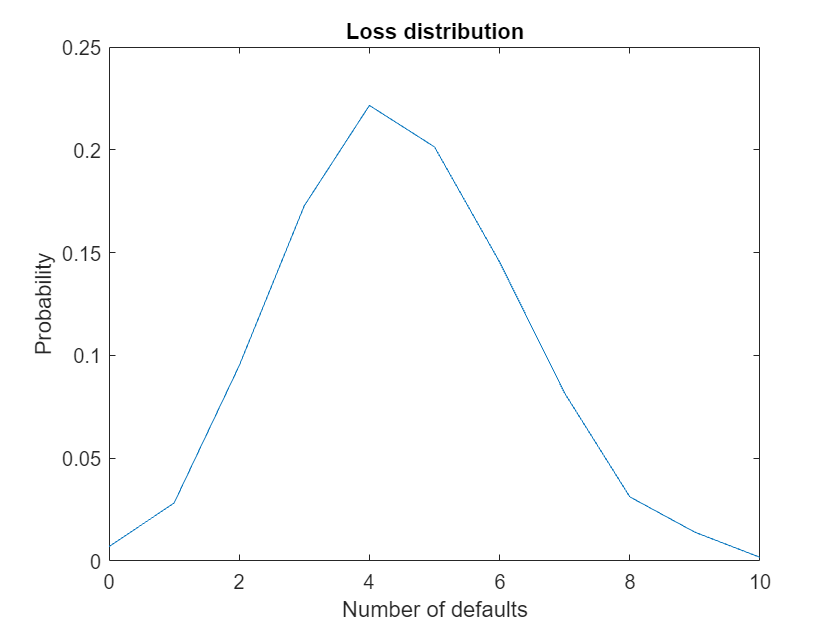

star_b2_small = model_B2.star(1, 1);
star_b2_small = star_b2_small.network;
star_b2_small = star_b2_small.monte_carlo(5000);
star_b2_small.plot_loss;

fprintf("Probability of systemic failure: %.2f", star_b2_small.probfail);

Probability of systemic failure: 0.02

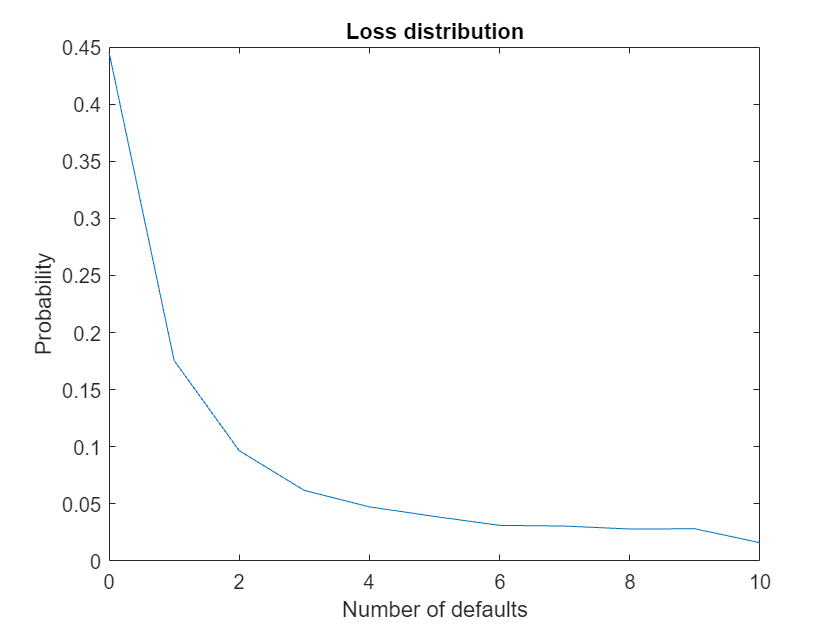

star_b2_med = model_B2.star(2, 9);
star_b2_med = star_b2_med.network;
star_b2_med = star_b2_med.monte_carlo(5000);
star_b2_med.plot_loss;

fprintf("Probability of systemic failure: %.2f", star_b2_med.probfail);

Probability of systemic failure: 0.02

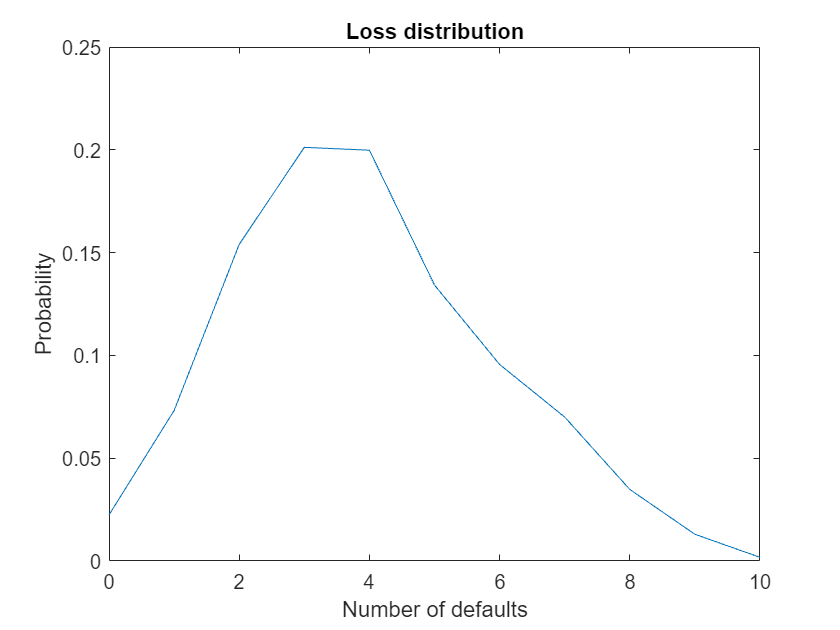

star_b2_large = model_B2.star(10, 10);
star_b2_large = star_b2_large.network;
star_b2_large = star_b2_large.monte_carlo(5000);
star_b2_large.plot_loss;

fprintf("Probability of systemic failure: %.2f", star_b2_large.probfail);

Probability of systemic failure: 0.02